% E8.2
clear all
syms s w

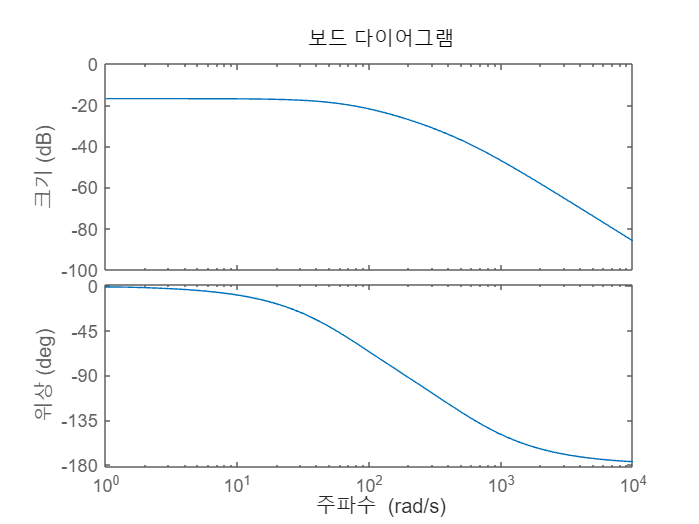

Gs = 5000/((s+70)*(s+500));
Gw = subs(Gs,s,j*w);
[n d] = numden(Gs);
num = sym2poly(n);
den = sym2poly(d);
sys = tf(num, den);
bode(sys)

simplify(Gw);
k = [10 200 700];
for c = k
    [pro deg] = bode(sys,c);
    mag = 20*log10(pro);
    fprintf("w = %.0f 일 때 크기 : %4.3f[dB]  위상 : %4.3f[°] \n", [c mag deg])
end

w = 10 일 때 크기 : -16.991[dB]  위상 : -9.276[°] 
w = 200 일 때 크기 : -27.167[dB]  위상 : -92.511[°] 
w = 700 일 때 크기 : -41.658[dB]  위상 : -138.752[°] 
